# Effort-constraint Reduction

## Introduction

Effort-constraint reduction of port-Hamiltonian systems is an energy-related method inspired by balanced truncation. It was introduced in [1,3].

### The idea (see [1,3])

Let us assume we are given a minimal (controllable and observable) port-Hamiltonian system in *co-energy coordinates *$e=Q\;x$ and **balanced representation **(i.e. the controllability Gramian $W_c$ and observability Gramian $W_o$ are equal):


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{e_1 } \\
\dot{e_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
Q_{11}  & Q_{12} \\
Q_{21}  & Q_{22} 
\end{array}\right\rbrack \left(\left\lbrack \begin{array}{cc}
J_{11}  & J_{12} \\
J_{21}  & J_{22} 
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
R_{11}  & R_{12} \\
R_{21}  & R_{22} 
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{c}
e_1 \\
e_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
Q_{11}  & Q_{12} \\
Q_{21}  & Q_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
G_1 \\
G_2 
\end{array}\right\rbrack u\\
y=\left\lbrack \begin{array}{cc}
G_1^T  & G_2^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
e_1 \\
e_2 
\end{array}\right\rbrack 
\end{array}$$


An equivalent representation is given by the *energy coordinates *$x=Q^{-1} \;e$


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\dot{x_1 } \\
\dot{x_2 } 
\end{array}\right\rbrack =\left(\left\lbrack \begin{array}{cc}
J_{11}  & J_{12} \\
J_{21}  & J_{22} 
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
R_{11}  & R_{12} \\
R_{21}  & R_{22} 
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{cc}
Q_{11}  & Q_{12} \\
Q_{21}  & Q_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
G_1 \\
G_2 
\end{array}\right\rbrack u\\
y=\left\lbrack \begin{array}{cc}
G_1^T  & G_2^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
Q_{11}  & Q_{12} \\
Q_{21}  & Q_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack 
\end{array}$$


*Note that the system is now expressed in energy coordinates but still balanced in co-energy coordinates!*

Let the second part of the state vector $e=\left\lbrack \begin{array}{c}
e_1 \\
e_2 
\end{array}\right\rbrack$be negligible since it is difficult to reach and to observe. We simplify by writing


$$e_2 = Q_{21} x_1 + Q_{22} x_2 \approx 0$$


from which we can deduce

$x_{2\;} \approx Q_{22}^{-1} \;Q_{21} \;x_1$.

Inserting both equations from above into the dynamic equations for the energy coordinates, one obtains


$$\dot{x}_1 = (J_{11} - R_{11}) (Q_{11} x_1 + Q_{12} x_2) + G_1 u\\
y = G_1^T (Q_{11} x_1 + Q_{12} x_2)$$


and finally


$$\dot{x}_1 = (J_{11} - R_{11}) (Q_{11} - Q_{12} Q_{22}^{-1} Q_{21})x_1 + G_1 u\\
y = G_1^T (Q_{11} + Q_{12} Q_{22}^{-1} Q_{21}) x_1$$


One can show that this reduced system still is of port-Hamiltonian form.

### Finding a balanced representation

As any linear system, we can write a port-Hamiltonian system in co-energy coordinates as


$$\begin{array}{l}
\dot{e} =A\;e+B\;u\\
y=C\;e+D\;u
\end{array}$$


For these systems, a balancing state transformation is found by $e_b = T_b e$ with


$$T_b =\Sigma^{-\frac{1}{2}} \;V^T R,\;\;\;\;\;\;T_b^{-1} =S^T \;U\;\Sigma^{-\frac{1}{2}}$$


where $W_c = S^T S$ and $W_o = R^TR$ are the cholesky factors of the Gramians and $S R^T = U \Sigma V^T$ is the singular value decomposition. [2]

Applying this state transformation to a port-Hamiltonian system retains the port-Hamiltonian properties.

## Toolbox implementation

The toolbox provides an implementation by the function *ecm*. It simply takes a port-Hamiltonian system and the desired reduced order as inputs.

The algorithm then finds a balanced representation by applying a state transformation as described above. We use *lyapchol* for finding the cholesky decomposition of the Gramians.

The balanced system is finally truncated with the Schur complement (see above).

help ecm

  ecm - computes the reduced port-Hamiltonian system model redSys for the
        full-order model sys using the effort-constraint method [1]
 
  Syntax:
    redSys = ecm(sys)
    redSys = ecm(sys, redOrder)
    redSys = ecm(sys, redOrder, Opts)
    redSys = ecm(sys, Opts)
    [redSys, sigma] = ecm(sys, ...)
 
  Description:
        redSys = ecm(sys, redOrder) computes the reduced
        port-Hamiltonian system redSys.
        The system will be transformed to a balanced co-energy
        representation first. Subsequently, the negligible directions (in
        energy coordinates) will be truncated. [1,2]
 
        Note that the algorithm applies some sort of symmetry correction to
        the reduced matrices J, R, and Q to prevent phs input validation
        failures.
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:		phs object
        - redOrder: desired ord

Due to the use of complex computations with the original system matrices, **effort-constraint reduction is relatively expensive**. Additionally, we observed occasional problems with the conditioning of the matrix $Q_{22}$.

## Example

We will consider a mass-spring-damper system with the following architecture

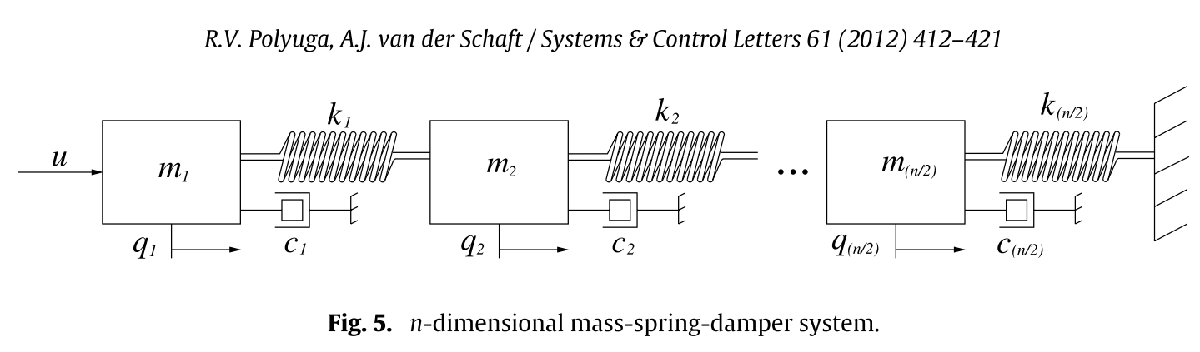

Image source: [3]

and $n = 100$, i.e. 50 masses ($m = 4$), 50 springs ($k = 4$), and 50 dampers ($d = 1$) .

sys = setup_MassSpringDamperSystem(100, 4, 4, 1, 'SISO')

sys =   phs with properties:

               J: [100×100 double]
               R: [100×100 double]
               Q: [100×100 double]
               G: [100×1 double]
               E: [100×100 double]
               P: [100×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 100
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


We reduce this system with *ecm *to order 20:

redSys = ecm(sys, 20)

redSys =   phsRed with properties:

      parameters: [1×1 struct]
          method: @ecm
            info: []
               J: [20×20 double]
               R: [20×20 double]
               Q: [20×20 double]
               G: [20×1 double]
               E: [20×20 double]
               P: [20×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 20
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


and finally compare the results by means of a bode plot and step response:

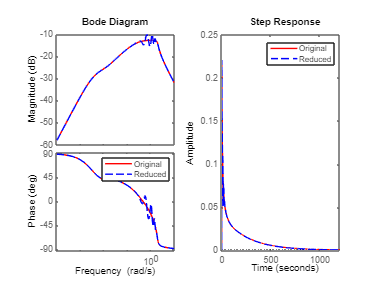

subplot(1, 2, 1)
bode(sys, 'r-', redSys, 'b--')
legend('Original', 'Reduced')
subplot(1, 2, 2)
step(sys, 'r-', redSys, 'b--')
legend('Original', 'Reduced')

## References

[1] Polyuga, R.V. (2010), *Model Reduction of Port-Hamiltonian Systems.* Thesis. University of Groningen.

[2] Benner, P. et al. (eds.) (2017), *Model reduction and approximation: Theory and algorithms.* Philadelphia: Society for Industrial and Applied Mathematics (Computational science and engineering, 15). Chapter 6

[3] Polyuaga et al. (2012), *Effort- and flow-constraint reduction methods for structure preserving model reduction of port-Hamiltonian systems*, in Systems & Control Letters 61(3)

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Julius Durmann    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)